% dist_target1 = norm(tessellation_target{16}(26,:)-tessellation_target{16}(30,:))
% 
% dist_close1 = norm(tessellation_close{16}(26,:)-tessellation_close{16}(30,:))
% 
% rate_1 = dist_target1/dist_close1
% 
% dist_target2 = norm(tessellation_target{16}(43,:)-tessellation_target{16}(44,:))
% 
% dist_close2 = norm(tessellation_close{16}(43,:)-tessellation_close{16}(44,:))
% 
% rate_2 = dist_target2/dist_close2
% 
% dist_gridtarget = norm(v_target(14,:) - v_target(15,:))
% 
% dist_gridclose = norm(v_out(14,:) - v_out(15,:))
% 
% rate_3 = dist_gridtarget/dist_gridclose
% 
% referece_rate = stretch_facs(1)

## Test the barycentric coordinate in undeformed and deformed

tri_old = [v_out(14,:);
    v_out(15,:);
    v_out(10,:)]

tri_old =   -20.1921   34.7073         0
   19.8079   34.7073         0
   -0.1921    0.0663         0


tri_new = [v_target(14,:);
    v_target(15,:);
    v_target(10,:)]

tri_new =   -21.5330   37.0751   25.7069
   21.3264   37.1346   25.7939
   -0.1342   -0.0002   49.9988



vertice1 = tessellation_close{16}(17,:)

vertice1 =     1.6000   33.5635         0


vertice2 = tessellation_target{16}(17,:)

vertice2 =     1.8158   35.8824   26.5550



dist1 = norm(tessellation_close{16}(17,:)-tessellation_close{16}(7,:))

dist1 = 21.1317

dist2 = norm(tessellation_target{16}(17,:)-tessellation_target{16}(7,:))

dist2 = 22.6424


bary1 = cart2barycentric(tri_old,vertice1)

bary1 =     0.4387    0.5283    0.0330


bary2 = cart2barycentric(tri_new,vertice2)

bary2 =     0.4387    0.5283    0.0330


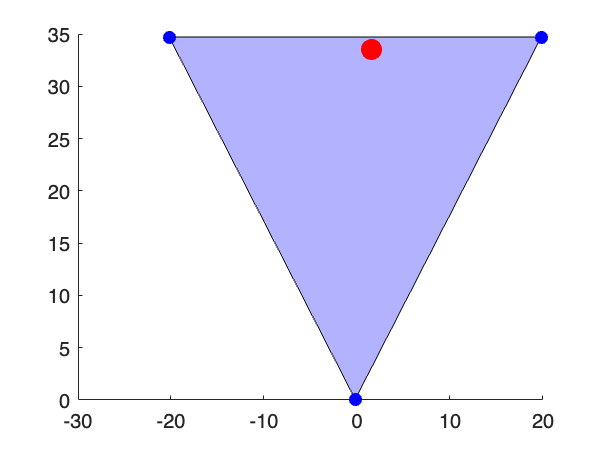


figure()
hold on
fill(tri_old(:,1), tri_old(:,2), 'b', 'FaceAlpha', 0.3, 'DisplayName', 'triangle\_1');
plot(tri_old(:,1), tri_old(:,2), 'bo', 'MarkerFaceColor', 'b'); % Triangle vertices
plot(vertice1(1), vertice1(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'vertice1'); % Special point
hold off

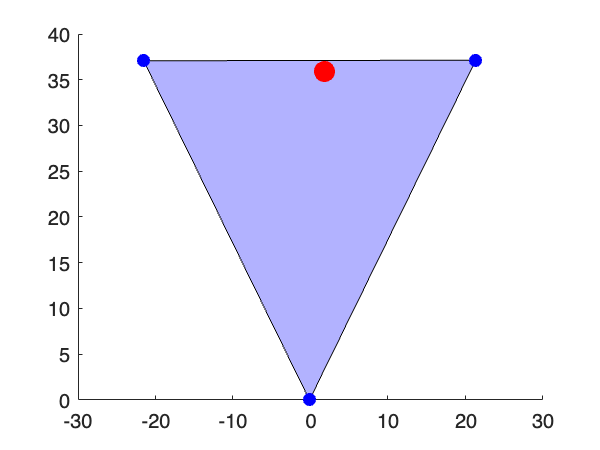


figure()
hold on
fill(tri_new(:,1), tri_new(:,2), 'b', 'FaceAlpha', 0.3, 'DisplayName', 'triangle\_1');
plot(tri_new(:,1), tri_new(:,2), 'bo', 'MarkerFaceColor', 'b'); % Triangle vertices
plot(vertice2(1), vertice2(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'vertice1'); % Special point
hold off